# Convective Heat Transfer

**Objective**: Simulate an energy balance model with convective heat transfer.

 viewSolution(false)

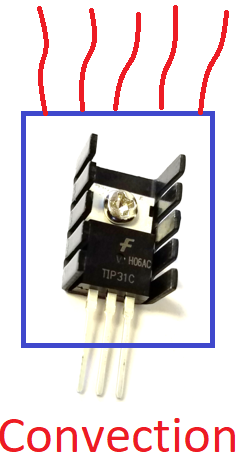

### Balance equation

A basic energy balance model of the Temperature Control Lab (TCLab) assumes that there is one uniform temperature in the control volume and that all heat loss is through natural convection with $U=10\frac{W}{m^2K$. The relationship between the heater and the power output is given by $\alpha=0.01 \frac{W}{\%}$.


$$m c_p \frac{dT}{dt}=UA(T_a-T) + \alpha Q$$


With the temperature initially at ambient temperature ($T_a$), simulate the change in temperature over the 5 minutes when heater $Q$ is adjusted to $50\%$. Use values of $m=0.004kg$, $A=0.0012m^2$, $c_p=500\frac{J}{kgK}$, and $T_a=23 ^\circ C$. Compare the simulated temperature response to data from the TCLab. **Add a simulation prediction to the script below to compare with the TCLab data.**

### Step Response Code

clc; clear all; close all;

Set Current Working Directory to the folder the liveScript is in

tmp = matlab.desktop.editor.getActive;
cd(fileparts(tmp.Filename));

Read results from file if the steptest has already run, otherwise, run the TCLab at 50% for about 5 minutes and record time and temperature. Then save as `filename`.csv

filename = "TCLab_data.csv";

try % try to read from file first
    A = readmatrix(filename)
    tm = A(:,1);
    T1 = A(:,2);
    
catch % if file can not be found, simulate
    try 
        % initialize lab
        lab = tclab;
        
        % loop through
        T1 = zeros(301, 1);
        tm = zeros(301, 1);
        lab.Q1(50);
        tic;
        for i=1:301
            tm(i) = toc;
            T1(i) = lab.T1;
            plot(tm(1:i), T1(1:i), 'ro')
            pause(1);
        end
        lab.off;
        clear lab;
        
        % save
        A = [tm T1]
        writematrix(A, filename, 'Delimiter', ',')
        
    catch % if an error, turn off heater and close
        lab.off;
        clear lab;
    end
    
end

### Simulation and Plot

ADD SIMULATION, CONVECTION DIFFERENTIAL EQUATION, AND PLOT BELOW. EDIT THE `convection_sim` FUNCTION TO ACCURATELY REFLECT THE SYSTEM

function dTdt = convection_sim()
    dTdt = 0;
    
end




### Solution

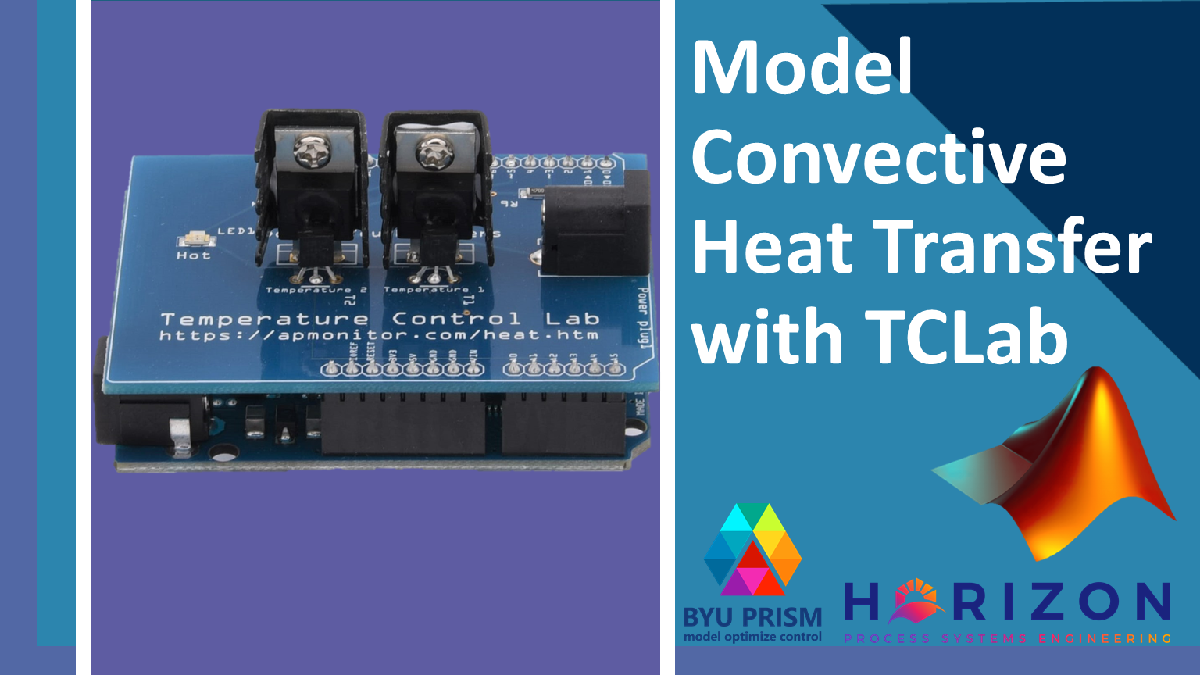

[View Solution Video](https://youtu.be/zsKMfVuyCV4)

% Solution Function
function viewSolution(view)
if view
     disp("t = linspace(0, 300, 301);" + newline + ...
     "" + newline + ...
     "[tt, Temp] = ode45(@(tt, Temp) convection_sim(tt, Temp), t, 23);" + newline + ...
     "" + newline + ...
     "% Plot" + newline + ...
     "plot(tm, T1, 'r.')" + newline + ...
     "hold on;" + newline + ...
     "plot(tt, Temp, 'b-')" + newline + ...
     "hold off;" + newline + ...
     "xlabel('Time (sec)')" + newline + ...
     "ylabel('Temperature (deg C)')" + newline + ...
     "legend({'Measured', 'Simulated'})" + newline + ...
     "" + newline + ...
     "function dTdt = convection_sim(tt, Temp)" + newline + ...
     "    U = 10;  % heat transfer (W/m^2 K)" + newline + ...
     "    Ta = 23;  % Ambient Temperature (deg C)" + newline + ...
     "    A = .0012;  % Area (m^2)" + newline + ...
     "    m = .004;  % Mass (Kg)" + newline + ...
     "    cp = 500;  % heat capacity (J / Kg K)" + newline + ...
     "    alpha = .01;  % (W/%)" + newline + ...
     "    Q = 50;  % percent power (%)" + newline + ...
     "    dTdt = (U*A*(Ta-Temp)+alpha*Q)/(m * cp);" + newline + ...
     "    " + newline + ...
	 "end")
end
end